# visualizing complex B_sec(t) 

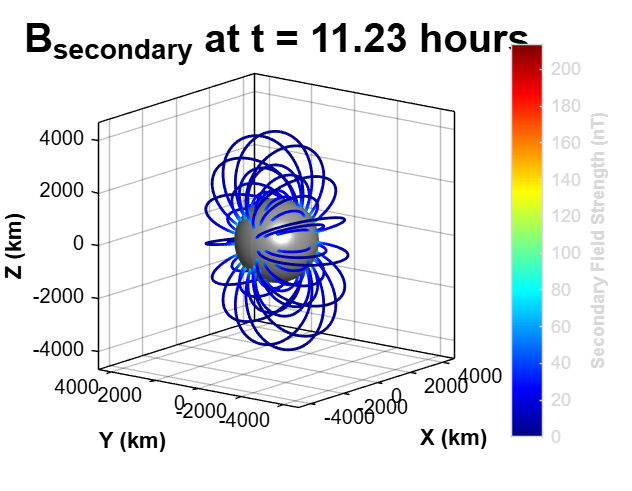

clear
% define constants
r_m = 1560; % Europa radius (km)
A = 0.95; % amplitude response factor
phi = 0.14; % phase lag in radians
synodic_period = 11.23 * 3600; % 11.23 hr period
omega = 2*pi / (synodic_period); % synodic freq. (rad/sec)

% elliptical primary field amplitudes from Zimmer's range (IS-system)
Bprim_x_amp = 67; 
Bprim_y_amp = 225;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% create spatial grid
grid_limit = 3 * r_m; 
num_points = 35;      
[X, Y, Z] = meshgrid(linspace(-grid_limit, grid_limit, num_points), ...
                     linspace(-grid_limit, grid_limit, num_points), ...
                     linspace(-grid_limit, grid_limit, num_points));

R = sqrt(X.^2 + Y.^2 + Z.^2);

% set up animation time array (60 steps over one full period)
num_frames = 60;
time_steps = linspace(0, synodic_period, num_frames);

% create figure once outside the loop 
fig = figure('Color', 'w');
set(gcf, 'Position', [100, 100, 900, 700]);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% animation loop 
for t = time_steps

    r_dot_e0x = X; % e0x = [1;0;0] -> r.e0x = X
    r_dot_e0y = Y; % e0y = [0;1;0] -> r.e0y = Y

    
    % complex secondary field: x-driven 
    coefx_c = -(A * Bprim_x_amp * r_m^3) .* exp(-1i*(omega * t - phi)) ./ (2 * R.^5);
    Bsecx_x = coefx_c .* (3 * r_dot_e0x .* X - R.^2);
    Bsecx_y = coefx_c .* (3 * r_dot_e0x .* Y);
    Bsecx_z = coefx_c .* (3 * r_dot_e0x .* Z);

    % complex secondary field: y-driven (90 deg / pi/2 shifted)
    coefy_c = -(A * Bprim_y_amp * r_m^3) .* exp(-1i*(omega*t - pi/2 - phi)) ./ (2 * R.^5);
    Bsecy_x = coefy_c .* (3 * r_dot_e0y .* X);
    Bsecy_y = coefy_c .* (3 * r_dot_e0y .* Y - R.^2);
    Bsecy_z = coefy_c .* (3 * r_dot_e0y .* Z);

    % sum the complex field components and isolate the real parts exactly once
    Bx = real(Bsecx_x + Bsecy_x);
    By = real(Bsecx_y + Bsecy_y);
    Bz = real(Bsecx_z + Bsecy_z);

    % avoid zero division 
    R_safe = R;
    R_safe(R_safe < 1e-3) = 1e-3;


    % take dynamic dipole geometry from complex parts 
    % to track the true, elliptically moving dipole moment axis over time:
    m_c_x = (A * Bprim_x_amp * r_m^3 / 2) * exp(-1i*(omega*t - phi));
    m_c_y = (A * Bprim_y_amp * r_m^3 / 2) * exp(-1i*(omega*t - pi/2 - phi));
    
    m_real = [real(m_c_x); real(m_c_y); 0];
    m_hat = m_real / norm(m_real); % true instantaneous unit axis vector

    % geometric seed finding for the equatorial plane
    v1 = cross(m_hat, [0; 0; 1]); 
    v1 = v1 / norm(v1);           % basis vector 1 (horizontal xy-plane)
    v2 = [0; 0; 1];               % basis vector 2 (vertical z-axis)
    
    num_seeds_per_ring = 16;
    theta = linspace(0, 2*pi, num_seeds_per_ring);
    radii_layers = [1.2, 1.8, 2.6] * r_m; 
    
    total_seeds = length(radii_layers) * num_seeds_per_ring;
    seed_X = zeros(1, total_seeds);
    seed_Y = zeros(1, total_seeds);
    seed_Z = zeros(1, total_seeds);
    
    idx = 1;
    for r_seed = radii_layers
        for k = 1:length(theta)
            pt = r_seed * (cos(theta(k))*v1 + sin(theta(k))*v2);
            seed_X(idx) = pt(1);
            seed_Y(idx) = pt(2);
            seed_Z(idx) = pt(3);
            idx = idx + 1;
        end
    end


    clf;
    set(gcf, 'Color', 'w');
    
    % draw solid Europa sphere
    [sx, sy, sz] = sphere(50);
    surf(sx*r_m, sy*r_m, sz*r_m, 'FaceColor', [0.7 0.7 0.7], ...
         'EdgeColor', 'none', 'FaceAlpha', 1.0);
    hold on;
    camlight('headlight'); lighting gouraud;

    % track field magnitude for streamline coloring
    B_mag = sqrt(Bx.^2 + By.^2 + Bz.^2);

    % generate streamline vertices
    verts_forward = stream3(X, Y, Z, Bx, By, Bz, seed_X(:), seed_Y(:), seed_Z(:));
    verts_backward = stream3(X, Y, Z, -Bx, -By, -Bz, seed_X(:), seed_Y(:), seed_Z(:));
    all_verts = [verts_forward; verts_backward];

    % render streamlines via colored patches
    for k = 1:numel(all_verts)
        v = all_verts{k};
        if isempty(v), continue; end

        line_colors = interp3(X, Y, Z, B_mag, v(:,1), v(:,2), v(:,3));

        patch('XData', v(:,1), 'YData', v(:,2), 'ZData', v(:,3), ...
              'FaceColor', 'none', 'EdgeColor', 'interp', ...
              'CData', line_colors, 'LineWidth', 1.4);
    end


    colormap(jet);
    c = colorbar;
    ylabel(c, 'Secondary Field Strength (nT)', 'FontWeight', 'bold');
    clim([0, A * Bprim_y_amp]); % bound limits to max theoretical response

    axis equal; grid on; box on;
    xlim([-grid_limit, grid_limit]);
    ylim([-grid_limit, grid_limit]);
    zlim([-grid_limit, grid_limit]);
    
    ax = gca;
    set(ax, 'XColor', 'k', 'YColor', 'k', 'ZColor', 'k', 'Color', 'w');
    xlabel('X (km)', 'FontWeight', 'bold');
    ylabel('Y (km)', 'FontWeight', 'bold');
    zlabel('Z (km)', 'FontWeight', 'bold');

    view([-52 14]); 
    title(sprintf('B_{secondary} at t = %.2f hours', t/3600), ...
          'Color', 'k', 'FontSize', 20, 'FontWeight', 'bold');

    drawnow;
    pause(0.04);
end